clc;
clear;
close all;

% Dati di specifica
Pn = 1000; % kVA
Vn2 = 10000; % V (Alta Tensione - AT)
Vn1 = 400; % V (Bassa Tensione - BT)
Vcc = 5.5; % Tensione di cortocircuito %
f = 50; % Hz
eta = 0.98; % Rendimento
COL1 = 1;
COL2 = 1;

% Dimensionamento della colonna
K = 1.45;
Phi_p = K * sqrt(Pn / f)* 10^-2; % Flusso di colonna primo tentativo (Wb)
Bc_p = 1.75; % T (Induzione primo tentativo)
kst = 0.93; % Coefficiente di stipamento
Scfe_p = Phi_p / Bc_p; % Sezione ferro di primo tentativo
Sc_p = Scfe_p / kst; % Sezione totale di primo tentativo
Sc_p_mm2 = Sc_p * 10^6; % Conversione in mm²
ku = 0.935; % Coefficiente di utilizzazione della colonna

% Diametro colonna
D = sqrt(4 * Sc_p / (pi * ku)); % Diametro colonna (m)

% Scelta numero gradini colonna e larghezza pacchetti
ngc = 6;
k = [0.967, 0.875, 0.768, 0.64, 0.483, 0.281]; % Larghezza dei pacchetti in p.u.
c = round(k * D * 1000); % Larghezza pacchetti (mm)

% Altezza pacchetti
b = zeros(1, ngc);
b(1) = sqrt((D * 1000)^2 - c(1)^2);
for i = 2:ngc
    b(i) = (sqrt((D * 1000)^2 - c(i)^2) - (b(1) + sum(2 * b(2:i-1))) ) / 2;
end
b = round(b); % Arrotondamento al mm

% Profondità colonna
L = sum([b(1), 2 * sum(b(2:end))]); % Altezza colonna in mm

% Calcolo delle sezioni dei pacchetti in mm²
Sp_mm2 = [c(1) * b(1), 2 * c(2) * b(2), 2 * c(3) * b(3), ...
          2 * c(4) * b(4), 2 * c(5) * b(5), 2 * c(6) * b(6)];

% Conversione in cm² (1 cm² = 100 mm²)
Sp_cm2 = Sp_mm2 * 10^(-2);

% Sezione lorda della colonna in cm²
Sc = sum(Sp_cm2);

% Sezione della colonna di solo ferro
Scfe = Sc * kst;

% Progetto del Giogo

% Coefficiente di sovradimensionamento della sezione del giogo
kg = 1.15;

% Determinazione delle larghezze dei pacchetti del giogo in mm
g = round(c * kg); % Arrotondamento al mm

% Altezza del giogo
Hg = g(1);

% Sezione lorda del giogo
Sg = Sc * kg; % cm^2

% Sezione del giogo di solo ferro
Sgfe = Scfe * kg;

% Flussi e induzioni di colonna e giogo

% Calcoli relativi alla tensione di fase e tensione di spira
% Tensione di fase nominale
Vf1 = Vn1 * sqrt(COL1 / 3); 

% Tensione di spira di primo tentativo
Vsp_p = (2 * pi / sqrt(2)) * Bc_p * Scfe * 10^(-4) * f;

% Numero di spire BT di primo tentativo
N1_p = Vf1 / Vsp_p;

% Definizione del numero di spire BT (arrotondato)
N1 = round(N1_p);

% Induzione di colonna effettiva
Bc = (Vf1 / (2 * pi / sqrt(2))) / (N1 * f * Scfe * 10^(-6));

% Flusso di colonna effettivo
Phi_c = Bc * Scfe * 10^(-6);

% Induzione effettiva nel giogo
Bg = (Bc * Scfe) / Sgfe;

% Tensione di spira effettiva
Vsp = Vf1 / N1;

% Altezza avvolgimento

In1 = (Pn * 1000) / (sqrt(3) * Vn1); % Corrente nominale (A)

If1 = In1;

Ai = 380; % Densità lineare corrente (A/cm)

h = round((N1 * In1) / Ai * 10); % Altezza colonna (mm)

% Distanze di isolamento
% Calcolo dei valori minimi
x_min = 25 + 1.26 * Vn2*10^(-3);
y_min = 40 + 1.7 * Vn2*10^(-3);
z_min = 0.85 * Vn2*10^(-3);

% Determinazione dei valori effettivi
x = 50;
y = 80;
z = 18;

% Battente d'olio tra giogo superiore e coperchio
hb_sup = 300; % mm

% Battente d'olio tra giogo inferiore e fondo
hb_inf = 50; % mm

% Sezione spira BT 
sigma1_p = 4.2; % Densità corrente primo tentativo (A/mm²)
Ssp1_p = In1 / sigma1_p; % Sezione spira primo tentativo (mm²)
a1 = 5.6; % Larghezza piattina BT (mm)
b1 = 12.5; % Altezza piattina BT (mm)
Sc1 = 69.1; % Sezione netta piattina (mm²)
bis1 = 0.59; % Bispessore isolamento (mm)

Ncs1 = ceil(Ssp1_p / Sc1); % Numero piattine in parallelo
Ssp1 = Ncs1 * Sc1; % Sezione effettiva spira (mm²)

% Numero di piattine in senso radiale
m1 = 2;

% Numero di piattine sovrapposte in senso assiale
n1 = Ncs1 * (N1 / m1);

% Densità effettiva di corrente
sigma1 = If1 / Ssp1;

% Altezza calcolata dell'avvolgimento
h_primo = (b1 + bis1) * Ncs1 * (N1 / 2 + 1);

% Errore rispetto all'altezza determinata
errore_h = abs(h - h_primo) / h * 100;

h1 = h; % è possibile compensare l'errore in fase di corstruzione 

% Distanza tra avvolgimenti
aca = 8; % mm (canale assiale)
acart = 4; % mm (spessore cartoccio)
theta1 = 2 * (a1 + bis1) + 4 * 0.5 + aca; % Dimensione assiale avvolgimento
D1i = D * 1000 + 2 * acart; % Diametro interno avvolgimento
D1e = D1i + 2 * theta1; % Diametro esterno avvolgimento
theta = aca + acart; % mm distana tra avvolfimento AT e BT

% Avvolgimento AT
Vf2 = Vn2 / sqrt(3);
N2 = round(Vf2 / Vsp);
In2 = (Pn * 1000) / (sqrt(3) * Vn2);

% Sezione spira AT
sigma2_p = 4.2; % A/mm²
Ssp2_p = In2 / sigma2_p; % Sezione spira AT (mm²)
a2 = 2.24; % mm
b2 = 6.3; % mm
Sc2 = 13.746; % mm²
bis2 = 0.55; % mm
Ncs2 = 1; % conduttori per spira 
m2 = 10; % piattie affiancate in senso radiale
n2 = 40; % piattie affiancate in senso assiale
Ssp2 = Ncs2 * Sc2;

% Calcolo dimensioni avvolgimento AT
theta2 = m2 * (a2 + bis2);
D2i = D1e + 2 * theta;
D2e = D2i + 2 * theta2;

% Interasse tra colonne e altezza trasformatore
X = D2e + z; % mm
H = h + 2 * x; % mm (altezza cassone)
a_col = c(1); % mm (larghezza colonna)

% Rapporto H/a_col
H_a_col = H / a_col;

% Rapporto X/a_col
X_a_col = X / a_col;

% Rapporto H/X
H_X = H / X;

% Rapporto L/a_col
L_a_col = L / a_col;

% Dimensinamento cassone

% Altezza cassone
Hcass = H + 2 * Hg + hb_sup + hb_inf;

% Raggio avvolgimento di AT
R2e = D2e / 2;

% Raggio di curvatura superficie laterale cassone
Rcass = R2e + y;

% Perdite totali teoriche
Pt = Pn * (1 - eta) / eta;

% Superficie totale di scambio termico
S = 38 * Pt * 1000; % cm^2

% Altezza dell'aletta
ha = 250; % mm

% Perimetro interno del cassone, esclusa alettatura
Pi = 4 * X + 2 * pi * Rcass; % mm

% Sviluppo perimetrale del mantello, inclusa alettatura
L = S * 10^2 / Hcass; % mm

% Numero teorico di alette
N_primo = (L - Pi) / (2 * ha);

% Numero di alette
N = round(N_primo);

% Passo di alettatura
tau_a = Pi / N;

% Scelta rapporto b/a
k = 2.8;

% Larghezza aletta
a = tau_a / (1 + k);

% Distanza tra alette
b_ = a * k;

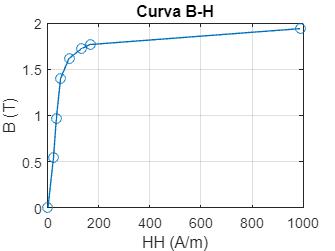

% Calcolo e Verifica

% Dati forniti per il lamierino usato
HH = [0, 21.45, 33, 49.5, 82.5, 132, 165, 990];
B = [0, 0.539394, 0.970909, 1.402424, 1.618182, 1.726061, 1.769212, 1.941818];

% Plotting della curva B-H
plot(HH, B, '-o');
xlabel('HH (A/m)');
ylabel('B (T)');
title('Curva B-H');
grid on;

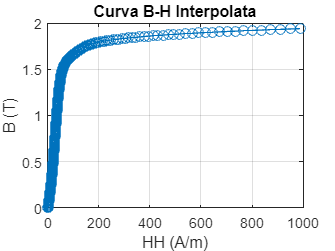



% Calcolo dell'interpolante cubica della curva H-B:
vs = spline(B, HH); 
y = @(x) ppval(vs, x);

% Generazione di punti per la curva interpolata
B_interp = linspace(min(B), max(B), 500);
HH_interp = y(B_interp);

% Plotting della curva interpolata
plot(HH_interp, B_interp, '-o');
xlabel('HH (A/m)');
ylabel('B (T)');
title('Curva B-H Interpolata');
grid on;


% Calcolo del campo H nella colonna e nel giogo:
Bc = 1.776; % T
Hc = y(Bc); % A/m

Bg = 1.544; % T
Hg = y(Bg); % A/m

% Calcolo del campo H nel traferro (equivalente):
mu0 = 4 * pi * 10^(-7); % H/m
Ha = Bc / mu0; % A/m

Lg = X + Hg / 2; % Lunghezza tratto circuito magnetico nel giogo (mm)

Lc = H; % Lunghezza tratto circuito magnetico colonna (mm)

La = 0.12;  % Lunghezza tratto circuito magnetico traferro (mm)

AStot = (Hc * Lc * 10^-3 + Hg * Lg * 10^-3 * (4/3) + 2 * Ha * La * 10^-3); % Amperspire medie totali per fase (A)

Im = AStot / (sqrt(2) * N1); % Corrente magnetizzante di fase (A)

Im_percent = (Im / If1) * 100; % Percentuale corrente magnetizzante (%)

% Perdite nel ferro

% Densità del nucleo laminato (kg/mm^3)
gamma_lam = 7.65e-6; 

% Massa delle colonne (kg) (Sc in cm^2)
Gc = 3 * Sc * 10^2 * H * gamma_lam; % Sc: sezione colonna (mm^2), H: altezza colonna (mm)

% Massa dei gioghi in zona non comprendente giunti (kg) (Sg in cm^2)
Gg1 = 4 * X * Sg * 10^2 * gamma_lam; % X: interasse colonne (mm), Sg: sezione giogo (mm^2)

% Massa dei gioghi in zona giunti (kg)
Gg2_A = b(1) * c(1) / 2 * g(1) + 2 * b(2) * c(2) / 2 * g(2) + 2 * b(2) * c(2) / 2 * g(2) + 2 * b(3) * c(3) / 2 * g(3); % b, c: dimensioni pacchetti (mm), g: larghezza pacchetti giunto (mm)
Gg2_B = 2 * b(4) * c(4) / 2 * g(4) + 2 * b(5) * c(5) / 2 * g(5) + 2 * b(6) * c(6) / 2 * g(6); 
Gg2 = 4 * (Gg2_A + Gg2_B) * gamma_lam; % kg

% Massa dei gioghi:
Gg = Gg1 + Gg2; % kg

% Massa del nucleo magnetico
Gfe = Gc + Gg; % kg

% Perdite specifiche in giogoo e colonna (da curva perdite a 50 Hz)
Bc = 1.776; % T
ps_c = 1.54; % W/kg  % Valore da curva perdite per Bc

Bg = 1.544; % T
ps_g = 1.1; % W/kg  % Valore da curva perdite per Bg

% Coefficiente di lavorazione
kL = 1.1;

% Coefficiente di maggiorazione delle perdite nella zona giunti
km = 1.5;

% Perdite nel ferro (isteresi + correnti parassite)
Pfe = (ps_c * Gc + ps_g * Gg1 + km * ps_g * Gg2) * kL; % W

% Perdite nel rame

% Calcolo dei diametri medi degli avvolgimenti
D1m = (D1i + D1e) / 2; % Diametro medio avvolgimento BT (mm)
D2m = (D2i + D2e) / 2; % Diametro medio avvolgimento AT (mm)

% Resistenza avvolgimenti in cc
r1cc = 0.021 * (pi * D1m * 10^-3) * N1 / Ssp1; % Resistenza avvolgimento BT (Ohm)
r2cc = 0.021 * (pi * D2m * 10^-3) * N2/ Ssp2; % Resistenza avvolgimento AT (Ohm)

% Altezza ridotta piattina BT
xi1 = 0.98 * a1 * 10^-1 * sqrt(n1 * b1 / h); % Altezza ridotta piattina BT

% Coefficiente di resistenza BT
kr1 = 1 + (m1^2 - 0.2) / 9 * xi1^4; % Coefficiente di resistenza BT

% Altezza ridotta piattina AT
xi2 = 0.98 * a2 * 10^-1 * sqrt(n2 * b2 / h1); % Altezza ridotta piattina AT

% Coefficiente di resistenza AT
kr2 = 1 + (m2^2 - 0.2) / 9 * xi2^4; % Coefficiente di resistenza AT

% Resistenze avvolgimenti in c.a. a 50 Hz
r1ca = r1cc * kr1; % Resistenza avvolgimento BT in c.a. (Ohm)
r2ca = r2cc * kr2; % Resistenza avvolgimento AT in c.a. (Ohm)

% Resistenza totale riportata sul lato BT
Rtot = r1ca + r2ca * (N1 / N2)^2; % Resistenza totale riferita al BT (Ohm)

% Perdite Joule a carico nominale
PJn = 3 * Rtot * If1^2; % Perdite Joule a carico nominale (W)

% Perdite Joule a vuoto
PJ0 = 3 * r1ca * Im^2; % Perdite Joule a vuoto (W)

% Corrente attiva nel funzionamento a vuoto
Ia = (PJ0 + Pfe) / (sqrt(3) * Vn1); % Corrente attiva a vuoto (A)

% Corrente a vuoto
I0 = sqrt(Im^2 + Ia^2); % Corrente a vuoto (A)

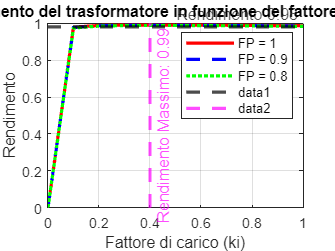

% Rendimento

% Rapporto perdite
rapporto_perdite = PJn / Pfe;

% Corrente di rendimento massimo (p.u.)
I_rend_max = sqrt(Pfe / PJn);

% Funzione per il calcolo del rendimento
% ki: fattore di carico (I/In)
% FP: fattore di potenza
rendimento = @(ki, FP) (Pn * 10^3 * ki * FP) ./ (Pn * 10^3 * ki * FP + Pfe + PJn * ki.^2);

% Plottaggio del rendimento in funzione del fattore di carico ki
ki = 0:0.1:1; % Vettore dei fattori di carico da 0 a 1 con passo 0.1
% Plot del rendimento per diversi fattori di potenza
figure; % Crea una nuova figura
plot(ki, rendimento(ki, 1), '-r', 'LineWidth', 2, 'DisplayName', 'FP = 1'); % FP = 1 (carico resistivo)
hold on; % Mantiene il grafico corrente
plot(ki, rendimento(ki, 0.9), '--b', 'LineWidth', 2, 'DisplayName', 'FP = 0.9'); % FP = 0.9 (carico induttivo)
plot(ki, rendimento(ki, 0.8), ':g', 'LineWidth', 2, 'DisplayName', 'FP = 0.8'); % FP = 0.8 (carico induttivo)

% Aggiungi retta orizzontale per rendimento 0.98
yline(0.98, '--k', 'LineWidth', 2, 'Label', 'Rendimento 0.98');

% Trova il valore massimo del rendimento e il relativo ki
[rend_max, index_max] = max(rendimento(ki, 1)); % Considera solo la curva con FP = 1 per il massimo
ki_max = ki(index_max);

% Aggiungi retta verticale per rendimento massimo
xline(ki_max, '--m', 'LineWidth', 2, 'Label', ['Rendimento Massimo: ', num2str(rend_max, '%.2f')]);

xlabel('Fattore di carico (ki)'); % Etichetta asse x
ylabel('Rendimento'); % Etichetta asse y (senza percentuale)
title('Rendimento del trasformatore in funzione del fattore di carico'); % Titolo del grafico
legend(); % Legenda (mostra le etichette definite nei plot)
grid on; % Griglia sul grafico
hold off; % Termina la modalità di mantenimento del grafico

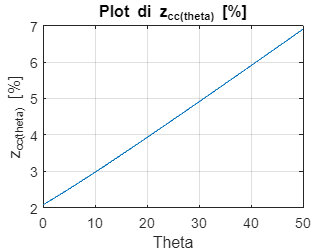

% Costante di permeabilità magnetica del vuoto
mu0 = 4 * pi * 10^-7; % H/m

% Induttanza di dispersione totale riferita al lato BT (H)
Ld = (mu0 / h) * pi * (D1m) * N1^2 * (theta1 / 3 + theta + theta2 / 3) * 10^-3;

% Reattanza di dispersione (Ohm)
Xtot = Ld * 2 * pi * f;

% Impedenza base (Ohm)
Zb = Vn1 / (sqrt(3) * In1);

% Impedenza di corto circuito (Ohm)
Zcc = sqrt(Rtot^2 + Xtot^2);

% Tensione di corto circuito (%)
Vcc_percent = (Zcc / Zb) * 100;

% Funzione per il calcolo della tensione di corto circuito al variare di theta
z_cc = @(theta) sqrt(Rtot^2 + ((mu0 / h) * pi * D1m * N1^2 * (theta1 / 3 + theta + theta2 / 3) * 10^-3 * 2 * pi * f)^2) / Zb * 100;

% Plot della funzione z_cc(theta)
theta_values = 0:0.1:50; % Valori di theta da 0 a 10 con passo 0.1
z_cc_values = arrayfun(z_cc, theta_values); % Calcola i valori di z_cc per ogni theta

plot(theta_values, z_cc_values);
title('Plot di z_cc(theta) [%]');
xlabel('Theta');
ylabel('z_cc(theta) [%]');
grid on;

% VERIFICA TERMICA DEL TRASFORMATORE

% **1. Stima ∆T medio del rame rispetto all'olio**

% Coefficienti di ricoprimento per canali assiali e radiali
k_ric_ass = 0.85; % Coefficiente di ricoprimento per canali assiali
k_ric_rad = 0.75; % Coefficiente di ricoprimento per canali radiali

% Superficie di dispersione termica equivalente per l'avvolgimento di BT (m^2)
Sdisp1 = 2 * pi * (D1m * 10^-3) * (h * 10^-3) * k_ric_ass; % (m^2)
% D1m: diametro medio avvolgimento BT (mm), h: altezza avvolgimenti (mm)

% Superficie di dispersione termica equivalente per l'avvolgimento di AT (m^2)
Sdisp2 = 2 * (b2 * 10^-3) * n2 * pi * (D2m * 10^-3) * k_ric_ass + 2 * n2 * pi * (D2m * 10^-3) * (theta2 * 10^-3) * k_ric_rad; % (m^2)
% b2: larghezza piattina AT (mm), n2: numero spire AT, D2m: diametro medio avvolgimento AT (mm), theta2: spazio tra avvolgimenti (mm)

% Flusso termico attraverso la superficie disperdente nell'avvolgimento di BT
q1 = (r1ca * If1^2) / Sdisp1; % (W/m^2)
% r1ca: resistenza avvolgimento BT (Ohm), If1: corrente nominale BT (A)

If2 = In2;
% Flusso termico attraverso la superficie disperdente nell'avvolgimento di AT (W/cm^2)
q2 = (r2ca * If2^2) / Sdisp2; % (W/m^2)
% r2ca: resistenza avvolgimento AT (Ohm), If2: corrente nominale AT (A)

% Coefficiente di scambio termico convettivo dell'olio per convezione naturale (W/(°C*m^2))
alpha_olio = 80; 

% Sovratemperatura media stimata del rame di BT rispetto all'olio (°C)
deltaT1 = q1 / alpha_olio;

% Sovratemperatura media stimata del rame di AT rispetto all'olio (°C)
deltaT2 = q2 / alpha_olio;

% **2. Stima ∆T massima dell'olio rispetto all'aria**

% Superficie disperdente del cassone che contribuisce all'irraggiamento (cm^2)
A = S * (tau_a / (2 * ha + tau_a)); % tau_a: passo alettatura (cm), ha: altezza aletta (cm)

% Flusso termico totale attraverso il cassone (W/m^2)
q = (PJn + Pfe) / (S * 10^-4); % PJn: perdite Joule nominali (W), Pfe: perdite nel ferro (W)

% Rapporto di irraggiamento
i = A / S;

% Sovratemperatura massima dell'olio rispetto all'aria (°C)
deltaT_max_olio_aria = 0.23 * q / (i + 0.8 + 0.001 * q);

% **3. Stima ∆T media dell'olio rispetto all'aria**

% Stima della sovratemperatura media del cassone rispetto all'aria (°C)
deltaT_med_cass_aria = 0.13 * q / (i + 0.8)

deltaT_med_cass_aria = 26.5299

% Stima della sovratemperatura media dell'olio rispetto all'aria (°C)
deltaT_med_olio_aria = (deltaT_max_olio_aria + deltaT_med_cass_aria) / 2;

% **4. Stima ∆T media del rame rispetto all'aria**

% Sovratemperatura media dell'avvolgimento sull'aria (°C)
deltaTavv_aria_1 = deltaT_med_olio_aria + deltaT1; % BT
deltaTavv_aria_2 = deltaT_med_olio_aria + deltaT2; % AT